%%%%%%%% User Input  %%%%%%%
Results_tag = date;  
fileName = strcat("Results_", Results_tag, "/Results.mat");
load(fileName)

t = linspace(1, 20, 1086); t=t';  % (!) 0 있으면 indeterminate % ★ 계속 사용

x1 = 60; x2 = 3; x3 = 70;  
z1 = 5; z2 = 3*0.9; z3 = 9; z4 = 5/2; z5 = 49;

y_byF = x1/20 * sin(2*pi*x2/10*t) + x3/10*log(t);  % ★ 계속 사용
y_byG = z1*z2/5 * cos(2*pi*sqrt(z3)/10*(t+z4)) + sqrt(z5)*log(t); 

amongNumGenerated = 300 % size(Result_Y, 2)/2;

amongNumGenerated = 300

%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% 하단에 %%% ★ 변경 %%% 에 유의

## 증강 데이터 확인, 2번째 WIFac 무작위 순서로 보기

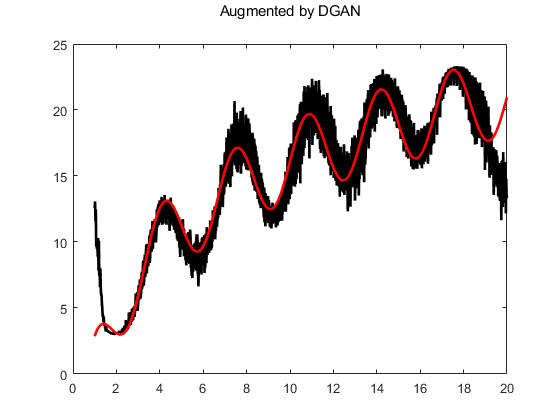

figure; 

for i = 1:10
    plot(t, Result_Y(:,i), 'k-', "LineWidth", 2)
    hold on
end 

% % 기준 y 곡선 plot
myplot = plot(t, y_byF, 'r', 'DisplayName', 'F(x)', "LineWidth", 2);

title(['Augmented by DGAN', newline])
xlim([0, 20]); ylim([0, 25]);

clf

second_WIFacs_first10 = [];

for i=1:10
    second_WIFacs_first10 = [second_WIFacs_first10, funcWIFac(t, y_byF, t(i), Result_Y(:,i))];
%     second_WIFacs_noSort = [second_WIFacs_first10, funcWIFac(t, y_byG, Result_Y(:,2*i-1), Result_Y(:,2*i))]; 
%     second_RMSEs_first10 = [second_RMSEs_first10, sqrt(mean((y_byG - Yaug_sortedSamp(:,2)).^2))];
end

second_WIFacs_first10

second_WIFacs_first10 = 1×10 single 행 벡터
    0.9003    0.9064    0.9055    0.9064    0.9047    0.8967    0.9021    0.9055    0.9036    0.9007


% second_RMSEs_first10

## Y 증강 데이터 확인, 2번째 WIFac 내림차순으로 보기

second_WIFacs_all = [];
% second_RMSEs_all = [];

for i=1:amongNumGenerated
    second_WIFacs_all = [second_WIFacs_all, funcWIFac(t, y_byF, t(i), Result_Y(:,i))];
%     second_RMSEs_all = [second_RMSEs_all, sqrt(mean((y_byG - Yaug_sortedSamp(:,2)).^2))];  % ★ second_RMSEs_all
end

second_WIFacs_all

second_WIFacs_all = 1×300 single 행 벡터
    0.9003    0.9064    0.9055    0.9064    0.9047    0.8967    0.9021    0.9055    0.9036    0.9007    0.9030    0.9086    0.9040    0.9067    0.9080    0.9038    0.9089    0.9066    0.9069    0.9064    0.8983    0.9047    0.9011    0.9029    0.9069    0.9070    0.9084    0.9065    0.9034    0.9093    0.9055    0.9065    0.9026    0.9065    0.9054    0.9047    0.9035    0.9062    0.9016    0.9077    0.8983    0.9051    0.9063    0.9054    0.9031    0.9069    0.9003    0.9046    0.9041    0.9081


[second_WIFacs_all_sort, second_WIFacs_all_sort_idx] = sort(second_WIFacs_all, 'descend');
second_WIFacs_all_sort

second_WIFacs_all_sort = 1×300 single 행 벡터
    0.9093    0.9089    0.9089    0.9088    0.9087    0.9087    0.9086    0.9086    0.9085    0.9084    0.9084    0.9083    0.9083    0.9082    0.9082    0.9081    0.9080    0.9080    0.9079    0.9078    0.9078    0.9078    0.9078    0.9078    0.9077    0.9077    0.9076    0.9076    0.9075    0.9074    0.9074    0.9073    0.9073    0.9073    0.9072    0.9071    0.9071    0.9071    0.9071    0.9071    0.9071    0.9070    0.9070    0.9070    0.9069    0.9069    0.9069    0.9069    0.9069    0.9069


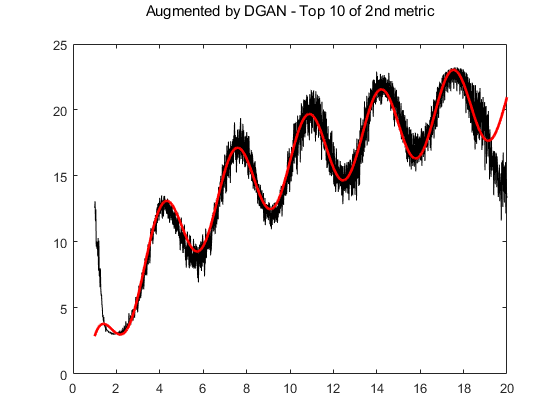


% second_RMSEs_all
% [second_RMSEs_all_sort, second_RMSEs_all_sort_idx] = sort(second_RMSEs_all);
% second_RMSEs_all_sort

figure; 

for i = second_WIFacs_all_sort_idx(1:10)  
    plot(t, Result_Y(:,i), 'k', "LineWidth", 0.5)
    hold on
end 

myplot = plot(t, y_byF, 'r', 'DisplayName', 'F(x)', "LineWidth", 2);

title(['Augmented by DGAN - Top 10 of 2nd metric', newline])
xlim([0, 20]); ylim([0, 25]);

clf

## 보너스. 한 개 샘플 통해서 순서 효과 보기

% i = 1;
% figure; ylim([-15, 15]); xlim([0, 3]);
% plot(Result_Y(:,2*i-1), Result_Y(:,2*i), 'k', "LineWidth", 0.5)
% hold on 
% plot(Result_Y(:,2*i-1), Result_Y(:,2*i), '.', "MarkerSize", 1)
% % % sort 하면
% figure; ylim([-15, 15]); xlim([0, 3]);
% 
% Yaug_sortedSamp = sortrows(Result_Y(:,i*2-1:i*2),1);
% plot(Yaug_sortedSamp(:,1), Yaug_sortedSamp(:,2), 'k', "LineWidth", 0.5)
% hold on 
% plot(Yaug_sortedSamp(:,1), Yaug_sortedSamp(:,2), '.', "MarkerSize", 1)
% clf

## 출력된 설계변수 데이터를 모델에 넣고 확인, 3번째 WIFac 무작위 10개 보기

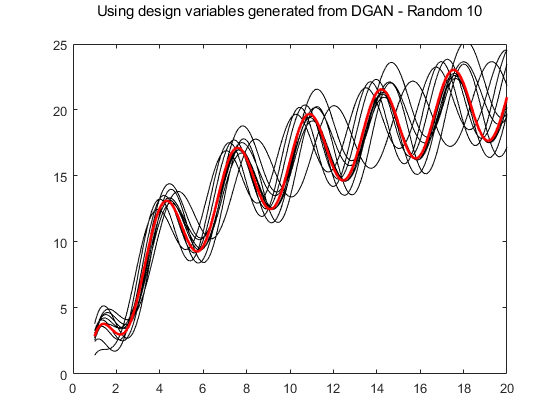

figure; 

third_WIFacs_first10 = []; 
% third_RMSEs_first10 = [];

for i = 1:10
    %%%%%%%%%% ★ 변경 %%%%%%%%%%
    z1 = Result_X1(i); z2 = Result_X2(i); z3 = Result_X3(i); z4 = Result_X4(i); z5 = Result_X5(i);
    Y_validate_DV = z1*z2/5 * cos(2*pi*sqrt(z3)/10*(t+z4)) + sqrt(z5)*log(t);
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    third_WIFacs_first10 = [third_WIFacs_first10, funcWIFac(t, y_byG, t, Y_validate_DV)];
%     third_RMSEs_first10 = [third_RMSEs_first10, sqrt(mean((y_byG - Y_validate_DV).^2))]; 
    
    plot(t, Y_validate_DV, 'k', "LineWidth", 0.5);
    hold on
end 

% % 기준 y 곡선 plot
myplot = plot(t, y_byF, 'r', 'DisplayName', 'F(x)', "LineWidth", 2);

title(['Using design variables generated from DGAN - Random 10', newline]);
xlim([0, 20]); ylim([0, 25]);

clf

third_WIFacs_first10

third_WIFacs_first10 = 1×10 single 행 벡터
    0.8928    0.9444    0.8229    0.9715    0.9591    0.8855    0.8643    0.9285    0.9367    0.8868


% third_RMSEs_first10

## 기준 y 곡선과 생성 곡선 하나씩 비교

% for i=1:10
%     z1 = Result_X1(i); z2 = Result_X2(i); z3 = Result_X3(i);
%     Y_validate_DV = z1/10*cos(z2/20*(t-2*(z3^(1/3))));
%     figure;
%     set(gcf,'position', [0, 0, 200, 200])  % [x0,y0,width,height]
%     plot(t, Y_validate_DV)
%     hold on
%     plot(t, y_byG)
% end
% 
% reset(gcf)
% clf

## 3번째 WIFac 전체 계산, 그리고 내림차순 정렬

third_WIFacs_all = []; 
% third_RMSEs_all = [];

for i=1:amongNumGenerated
    %%%%%%%%%% ★ 변경 %%%%%%%%%%
    z1 = Result_X1(i); z2 = Result_X2(i); z3 = Result_X3(i); z4 = Result_X4(i); z5 = Result_X5(i);
    Y_validate_DV = z1*z2/5 * cos(2*pi*sqrt(z3)/10*(t+z4)) + sqrt(z5)*log(t);
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    third_WIFacs_all = [third_WIFacs_all, funcWIFac(t, y_byG, t, Y_validate_DV)];
%     third_RMSEs_all = [third_RMSEs_all, sqrt(mean((y_byG - Y_validate_DV).^2))];  % ★ third_RMSEs_all
end

third_WIFacs_all

third_WIFacs_all = 1×300 single 행 벡터
    0.8928    0.9444    0.8229    0.9715    0.9591    0.8855    0.8643    0.9285    0.9367    0.8868    0.9555    0.9437    0.9384    0.9136    0.9265    0.8693    0.8950    0.9590    0.9321    0.8885    0.8922    0.9198    0.9076    0.9409    0.9184    0.9069    0.8995    0.9568    0.9449    0.9185    0.9571    0.9133    0.9311    0.9389    0.9664    0.8919    0.8587    0.9236    0.9218    0.9101    0.9127    0.9552    0.8990    0.9686    0.9415    0.9692    0.9628    0.8562    0.9259    0.8997


[third_WIFacs_all_sort, third_WIFacs_all_sort_idx] = sort(third_WIFacs_all, 'descend');
third_WIFacs_all_sort

third_WIFacs_all_sort = 1×300 single 행 벡터
    0.9816    0.9794    0.9786    0.9780    0.9776    0.9772    0.9764    0.9750    0.9749    0.9746    0.9745    0.9734    0.9715    0.9705    0.9692    0.9686    0.9682    0.9679    0.9679    0.9678    0.9673    0.9672    0.9672    0.9667    0.9666    0.9664    0.9651    0.9645    0.9641    0.9640    0.9639    0.9628    0.9627    0.9627    0.9623    0.9621    0.9615    0.9613    0.9596    0.9591    0.9590    0.9580    0.9571    0.9568    0.9559    0.9556    0.9556    0.9555    0.9552    0.9552



% third_RMSEs_all
% [third_RMSEs_all_sort, third_RMSEs_all_sort_idx] = sort(third_RMSEs_all);
% third_RMSEs_all_sort

## 출력된 설계변수 데이터를 모델에 넣고 확인, 3번째 WIFac 내림차순 첫 10개 샘플 통해 시각화하기

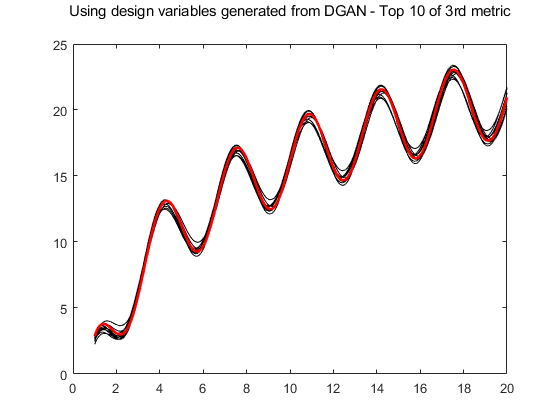

figure; 
j=1;
for i = third_WIFacs_all_sort_idx(1:10)  
    %%%%%%%%%% ★ 변경 %%%%%%%%%%
    z1 = Result_X1(i); z2 = Result_X2(i); z3 = Result_X3(i); z4 = Result_X4(i); z5 = Result_X5(i);
    Y_validate_DV = z1*z2/5 * cos(2*pi*sqrt(z3)/10*(t+z4)) + sqrt(z5)*log(t);
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    plot(t, Y_validate_DV, 'k', "LineWidth", 0.5);
    gap(j)=max(Y_validate_DV(168:446))-min(Y_validate_DV(168:446));
    j=j+1;
    hold on
    save(1,j) = Result_X1(i);
    save(2,j) = Result_X2(i);
    save(3,j) = Result_X3(i);
    save(4,j) = Result_X4(i);
    save(5,j) = Result_X5(i);
end 

% % 기존 y 곡선 plot
myplot = plot(t, y_byF, 'r', 'DisplayName', 'F(x)', "LineWidth", 2);
gap(j)=max(y_byF(168:446))-min(y_byF(168:446));

title(['Using design variables generated from DGAN - Top 10 of 3rd metric', newline])
xlim([0, 20]); ylim([0, 25]);

clf

Name = ["2nd WIFac(descend)"; "3rd WIFac(descend)"];
AATop10Metrics = [second_WIFacs_all_sort(1:10), mean(second_WIFacs_all_sort(1:10)); third_WIFacs_all_sort(1:10), mean(third_WIFacs_all_sort(1:10))];
AATop10_Metrics_Table = table(Name, AATop10Metrics)

AATop10_Metrics_Table = 2×2 table
            Name            AATop10Metrics
    ____________________    ______________

    "2nd WIFac(descend)"    [1×11 single] 
    "3rd WIFac(descend)"    [1×11 single] 



Name2 = ["x1"; "x2"; "x3"; "x4"; "x5"];
iidx = third_WIFacs_all_sort_idx(1:10);
AADVuseTop10MetricsStats = [mean(Result_X1(iidx)), std(Result_X1(iidx)); mean(Result_X2(iidx)), std(Result_X2(iidx)); 
                          mean(Result_X3(iidx)), std(Result_X3(iidx)); mean(Result_X4(iidx)), std(Result_X4(iidx));
                          mean(Result_X5(iidx)), std(Result_X5(iidx))];
AADV_useTop10Metrics_Stats_Table = table(Name2, AADVuseTop10MetricsStats)

AADV_useTop10Metrics_Stats_Table = 5×2 table
    Name2    AADVuseTop10MetricsStats
    _____    ________________________

    "x1"        4.9347     0.20529   
    "x2"        2.9006     0.19303   
    "x3"        8.9468     0.11389   
    "x4"         2.561    0.077376   
    "x5"        48.848      1.1603   
